# Comparison of Growth Kinetics Using Smoluchowski Coagulation Times and Optical Cluster Sizes

The idea is that we will compare the coagulation time resulting from a fit of the NL Smoluchowski model to the optical clusters (because they all have the general fast-then-slower growth pattern) to the coagulation time of the NL Smol model of the contact clusters (although a lot of them are close to linear, at least that way you're using the same fit for all of them).  Also compare the exponents? or is that less relevant? Let's check.

 We should *also* find a way to characterize the different contact cluster growth types (I'm not 100% convinced that I'm pulling out "lag phase" well?  Perhaps a *number* on the lag phase from the fit?)  but this is for analysis of effects rather than choice of "best model".

Okay I think we're going to have to minimize for the optical lambda for all the parameters and then compare the tcs, because the comparison with lambdas *and* tcs is difficult.  

This means assuming that the homogeneity relation is the same 

## NL Smoluchowski: Effects of the two parameters

Assume monodisperse initial conditions because that's easiest.

smolfunc = @(t,tc,lambda) (1+2*t/tc).^(1/(1-lambda));
ts = 0:799;
tc = 10;
figure()
hold on
for lambda = -1:0.2:0
   plot(ts,smolfunc(ts,tc,lambda),'linewidth',2) 
end
lambda = -0.5

lambda = -0.5000

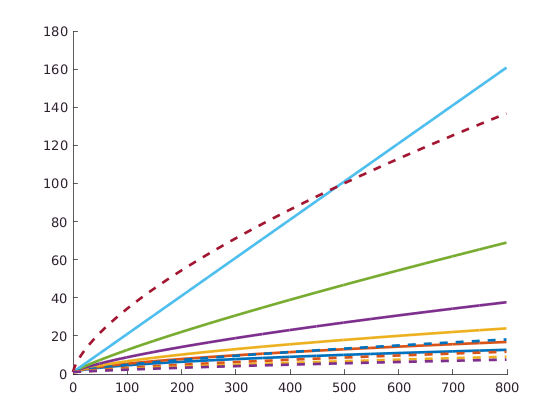


for t = 1:20:100
    plot(ts,smolfunc(ts,t,lambda),'--','linewidth',2)
end

## NL Smoluchowski: Extracting the Homogeneity Relation from Data

The homogeneity relation says that $K_{ai,aj} = a^\lambda K_{i,j}$, where K(i,j) is the rate at which mers of size i+j are formed from clusters of size i and size j.  It's reasonable easy to compute this rate when i = j from the cluster sizes.  It also leads to the equation $\lambda = \frac{1}{\log(a)}\log\left(\frac{K_{ai,aj}}{K_{i,j}} \right)$, meaning we can compute lambda repeatedly at different a values and see whether the homogeneity relation approximately holds.

addpath('/home/rachael/Analysis_and_run_code/lab_notebook/CG_patchy/helper_fcns');
cSizesTest = importdata('/home/rachael/cluster/scratch/ramansbach/coarsegraining/hoomd/patchy/analyze/250-2-100/mols10000_250-2-100_short_runcut0.351optical-sizes.dat');
K11 = computeRate(1,1,cSizesTest);%rate of dimer formation
lambdas = zeros(1,49);
for a = 2:50
    Ka1a1 = computeRate(a,1,cSizesTest);
    lambdas(a-1) = (1/log(a))*log(Ka1a1/K11);
end

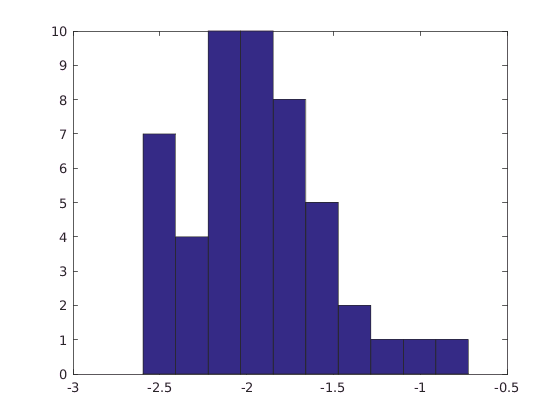

figure()
hist(lambdas)

fprintf('Mean lambda is: %f +/- %f',mean(lambdas(~isinf(lambdas))),std(lambdas(~isinf(lambdas))));

Mean lambda is: -1.906913 +/- 0.379077

cSizesTest = importdata('/home/rachael/cluster/scratch/ramansbach/coarsegraining/hoomd/patchy/analyze/500-6-150/mols10000_500-6-150_short_runcut0.351optical-sizes.dat');
K11 = computeRate(1,1,cSizesTest);%rate of dimer formation
lambdas = zeros(1,10*49);
ind = 1;
for j = 1:10
    Kjj = computeRate(j,1,cSizesTest);
for a = 2:50
    Ka1a1 = computeRate(a,j,cSizesTest);
    lambdas(ind) = (1/log(a))*log(Ka1a1/Kjj);
    ind = ind+1;
end
end

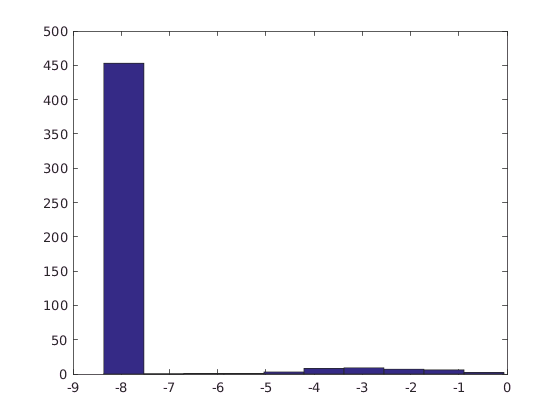

figure()
hist(lambdas)

fprintf('Mean lambda is: %f +/- %f',mean(lambdas(~isinf(lambdas))),std(lambdas(~isinf(lambdas))));

Mean lambda is: -2.967777 +/- 1.625380

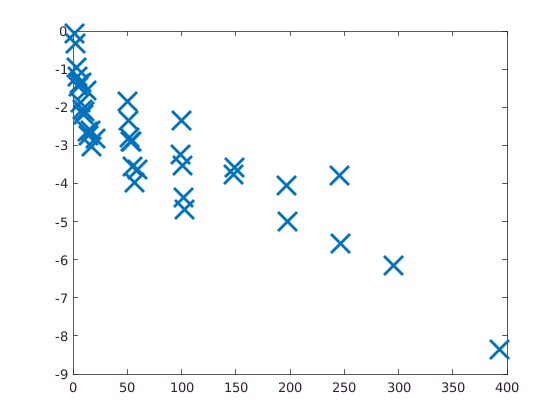

figure()
plot(lambdas,'x','markersize',20,'linewidth',2)

Okay, so we've got a pretty big spread in these lambdas (and this is *only* including a subset of rate computations!), meaning that I feel like for a comparison, it's okay to average these to get a ballpark (encouragingly at least these are negative!) which can then be used over the opticals for fits to compare their coagulation times.

Hmmm, this says the homogeneity assumption is *not* a great assumption.  It's not really true that the rate of larger cluster aggregation is dependent on the rate of smaller cluster aggregation in a simple way.  So what do we do now?  Throwing out the homogeneity assumption leaves us without a very clear model--the Smoluchowski model is no longer a terribly good one (because everything becomes complicated).

Okay, so, here's the problem: optical clusters are much smaller than contact clusters, so their growth rate is being partially controlled by rearrangements *within* contact clusters and they aren't super amenable to Smoluchowski analysis with homogeneity because of that.  We could argue that an L method will give us approximately two linear regimes where the first comes from the average rate of growth of optical clusters from primarily free monomers whereas the second is the average rate from *within* a contact cluster.  The first is smaller because the contact clusters are more loosely defined.  Then what is interesting is the timescale of the *second* regime.

So we essentially have two metrics: timescale of optical cluster size growth and ratio of that timescale to the contact timescale.

## Read in Data

mu2contactMats = {};
mu2opticalMats = {};

paramDict = {};
tstart = 10; %cut off timesteps
fileLocation = '/home/rachael/cluster/scratch/ramansbach/coarsegraining/hoomd/patchy/analyze/';
AAnames = {'250','500','750'};
SCnames = {'02','2','4','6','10'};
Signames = {'025','050','075','100','125','150','200'};
AAparams = [2.5,5,7.5];
SCparams = [0.2,2,4,6,10];
Sigparams = [0.25,0.5,0.75,1.0,1.25,1.5,2.0];
fbase = 'mols10000_';
bParams = zeros(length(AAnames),length(Signames),length(SCnames));
cEnds = zeros(length(AAnames),length(Signames),length(SCnames));
oEnds = zeros(length(AAnames),length(Signames),length(SCnames));


for i = 1:length(AAnames)
    for sc = 1:length(SCnames)
        for sig = 1:length(Signames)
    foldname = [fileLocation AAnames{i} '-' SCnames{sc} '-' Signames{sig} '/'];
    
    fname = [foldname fbase AAnames{i} '-' SCnames{sc} '-' Signames{sig} '_short_run-contact-mu2s.dat'];
    
    fnameo = [foldname fbase AAnames{i} '-' SCnames{sc} '-' Signames{sig} '_short_run-optical-mu2s.dat'];  
    try
       dataMatrix = importdata(fname);
       dataMatrix = dataMatrix(tstart:end,:);
      
       dataMatrixo = importdata(fnameo);
       dataMatrixo = dataMatrixo(tstart:end,:);
    catch
       fprintf('No data for %s\n',[AAnames{i} '-' SCnames{sc} '-' Signames{sig}])
       dataMatrix = []; 
       dataMatrixo = [];
    
    end
    
    if ~isempty(dataMatrix)
        cEnds(i,sig,sc) = dataMatrix(end);
        oEnds(i,sig,sc) = dataMatrixo(end);
    end
    mu2contactMats{i}{sc}{sig} = dataMatrix;
    mu2opticalMats{i}{sc}{sig} = dataMatrixo;
    
    AA = str2double(AAnames{i})/100;
    if strcmp(SCnames{sc},'02')
       SC = 0.2; 
    else
       SC = str2double(SCnames{sc}); 
    end
    
    if strcmp(Signames{sig},'001')
        SIG = 0.01;
    elseif strcmp(Signames{sig},'06')
        SIG = 0.6;
    else
        SIG = str2double(Signames{sig})/100;
    end
    paramDict{i}{sc}{sig} = [AA,SC,SIG];
        end
    end
end

No data for 250-02-100
No data for 250-02-150
No data for 250-02-200
No data for 250-4-100
No data for 250-4-150
No data for 250-4-200
No data for 250-6-025
No data for 250-6-050
No data for 250-6-075
No data for 250-6-125
No data for 250-10-025
No data for 250-10-050
No data for 250-10-075
No data for 250-10-125
No data for 500-02-100
No data for 500-02-150
No data for 500-02-200
No data for 500-4-100
No data for 500-4-150
No data for 500-4-200
No data for 500-6-025
No data for 500-6-050
No data for 500-6-075
No data for 500-6-125
No data for 500-10-025
No data for 500-10-050
No data for 500-10-075
No data for 500-10-125
No data for 750-02-100
No data for 750-02-150
No data for 750-02-200
No data for 750-4-100
No data for 750-4-150
No data for 750-4-200
No data for 750-6-025
No data for 750-6-050
No data for 750-6-075
No data for 750-6-125
No data for 750-10-025
No data for 750-10-050
No data for 750-10-075
No data for 750-10-125


## Extract Timescales for Optical and Contact Clusters

addpath('/home/rachael/Analysis_and_run_code/stats_analysis/');
savefold = '/home/rachael/coarsegraining/Data/patchy/';
warning('off','curvefit:fit:noStartPoint')
tcharCs = NaN*ones(length(AAnames),length(SCnames),length(Signames));
tcharOs = NaN*ones(length(AAnames),length(SCnames),length(Signames));
tic
AIC1s = NaN*ones(length(AAnames),length(SCnames),length(Signames));
AIC2s = NaN*ones(length(AAnames),length(SCnames),length(Signames));
for i = 1:length(AAnames)
    for sc = 1:length(SCnames)
        for sig = 1:length(Signames)
            cMat = mu2contactMats{i}{sc}{sig};
            cMatO = mu2opticalMats{i}{sc}{sig};
            
            if ~isempty(cMat)
           
            
            
            mmu2s = mean(cMat,2);
            smu2s = std(cMat,[],2);
            [lf,glf] = fit((1:length(cMat(1:2:end,:)))',mean(cMat(1:2:end,:),2),'poly1');
            mu2sO = mean(cMatO,2);
            
            if size(cMatO,2) > 1
                [l1,l2,splt,lsing,aic1,aic2,fig1,fig2] = Lmethod(1:length(cMatO(1:2:end,:)),mean(cMatO(1:2:end,:),2),std(cMatO(1:2:end),0,1),1);
            else
                [l1,l2,splt,lsing,aic1,aic2,fig1,fig2] = Lmethod(1:length(cMatO(1:2:end,:)),mean(cMatO(1:2:end,:),2),[],0);
            end
            AIC1s(i,sc,sig) = aic1;
            AIC2s(i,sc,sig) = aic2;
            if aic1 < aic2
                tcharO = lsing.a;
            else
                tcharO = 1/l2.a;
            end
            tcharC = 1/lf.p1;
            tcharCs(i,sc,sig) = tcharC;
            tcharOs(i,sc,sig) = tcharO;
            
            fig3 = figure();
            set(gca,'fontsize',20)
            hold on
            plot(cMat(1:2:end,:))
            plot(1:length(cMat(1:2:end,:)),lf(1:length(cMat(1:2:end,:))),'m--','linewidth',2)
            title([AAnames{i} '-' SCnames{sc} '-' Signames{sig} ', Contact'])
            savefig(fig1,[savefold AAnames{i} '-' SCnames{sc} '-' Signames{sig} 'optfit1'])
            saveas(fig1,[savefold AAnames{i} '-' SCnames{sc} '-' Signames{sig} 'optfit1'],'pdf')
            savefig(fig2,[savefold AAnames{i} '-' SCnames{sc} '-' Signames{sig} 'optfit2'])
            saveas(fig2,[savefold AAnames{i} '-' SCnames{sc} '-' Signames{sig} 'optfit2'],'pdf')
            savefig(fig3,[savefold AAnames{i} '-' SCnames{sc} '-' Signames{sig} 'confit'])
            saveas(fig3,[savefold AAnames{i} '-' SCnames{sc} '-' Signames{sig} 'confit'],'pdf')
            close(fig1)
            close(fig2)
            close(fig3)
            end
        end
    end
end
toc

Elapsed time is 1678.829464 seconds.


## Visualization

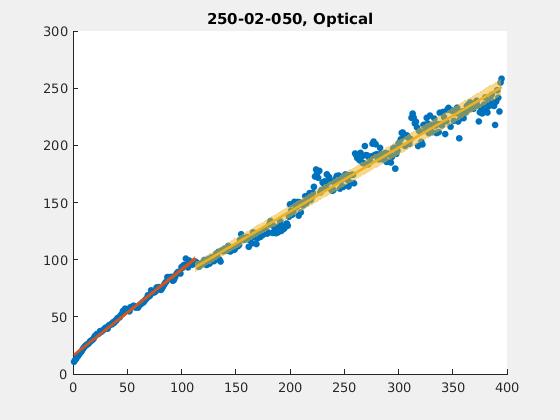

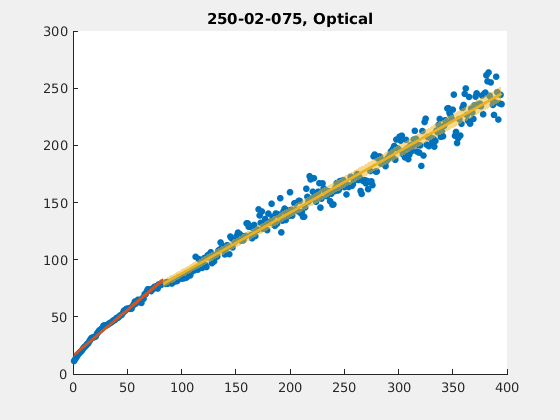

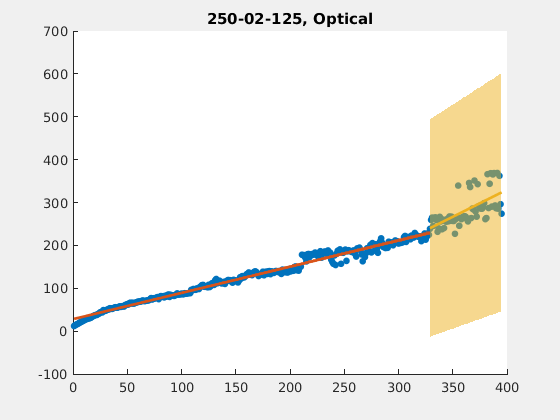

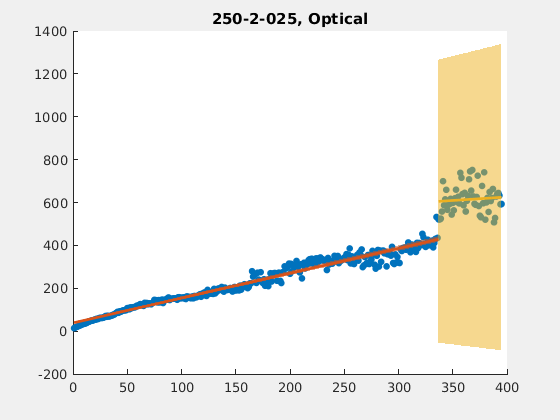

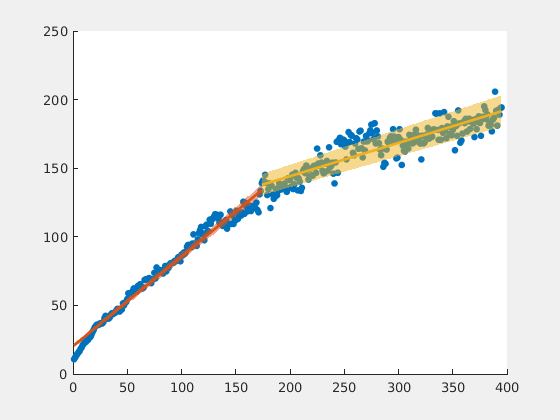

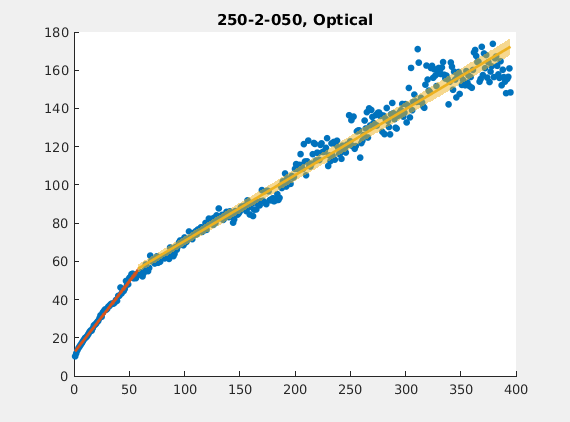

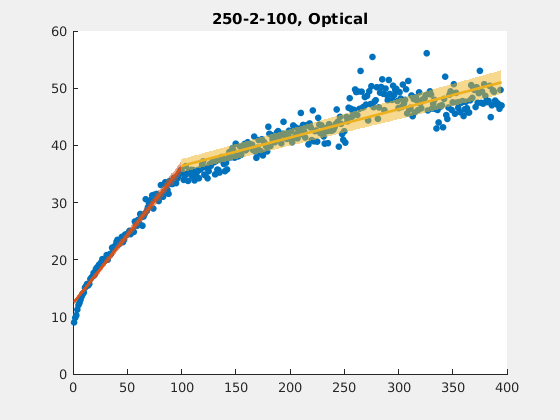

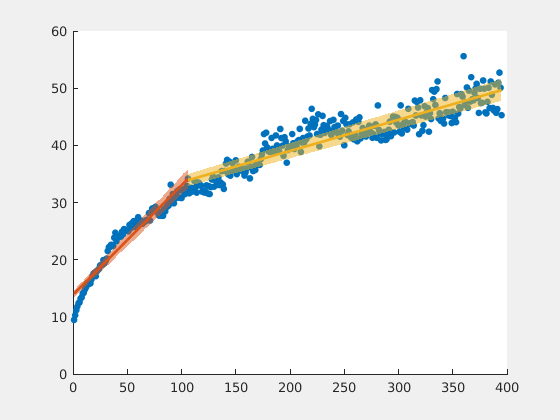

for i = 1:length(AAnames)
    for sc = 1:length(SCnames)
        for sig = 1:length(Signames)
             cMat = mu2contactMats{i}{sc}{sig};
             if ~isempty(cMat)
            %openfig([savefold AAnames{i} '-' SCnames{sc} '-' Signames{sig} 'optfit1'],'visible');
            %fprintf([AAnames{i} '-' SCnames{sc} '-' Signames{sig} '\n' ])
            fig2 = openfig([savefold AAnames{i} '-' SCnames{sc} '-' Signames{sig} 'optfit2'],'visible');
            hold on
            %set(gca,'fontsize',20)
            title([AAnames{i} '-' SCnames{sc} '-' Signames{sig} ', Optical']);
            %savefig(fig2,[savefold AAnames{i} '-' SCnames{sc} '-' Signames{sig} 'optfit2'])
            %saveas(fig2,[savefold AAnames{i} '-' SCnames{sc} '-' Signames{sig} 'optfit2'],'pdf')
            %openfig([savefold AAnames{i} '-' SCnames{sc} '-' Signames{sig} 'confit'],'visible');
             end
         end
    end
end

## Timescale of optical cluster growth

<mu2> is currently in units of just the number of monomers in a cluster, so the slopes are in units of 1/time.

2 x 10^7 steps of 0.001 tau_patchy -> divide into 400 steps -> 50 000 (0.001 tau patchy) size per step

-> 1825 ns per step in this case

**Show in 2D**

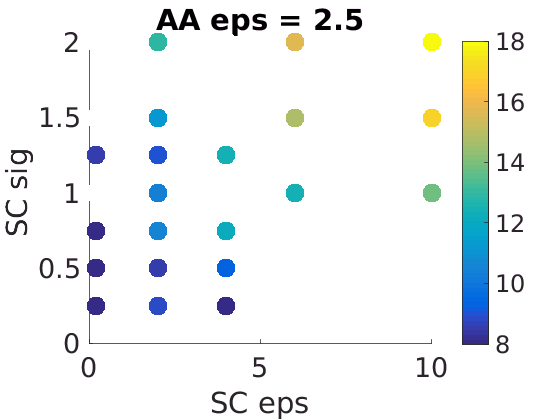

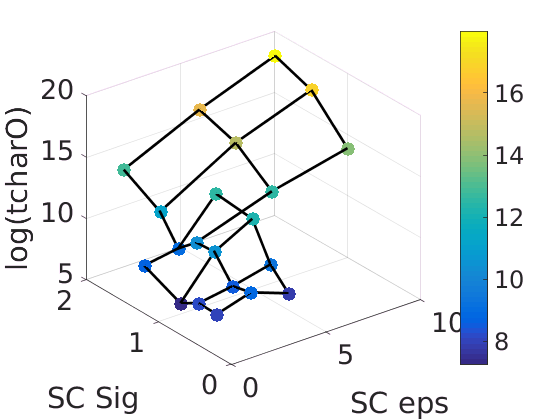

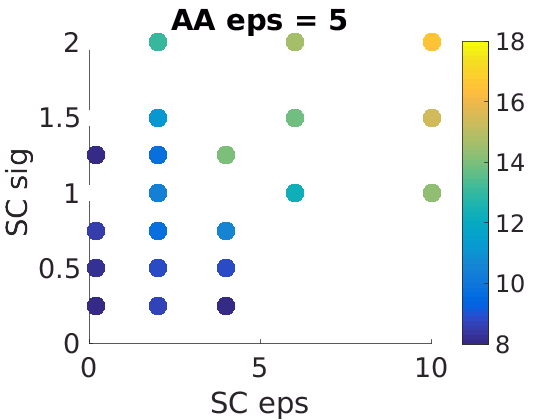

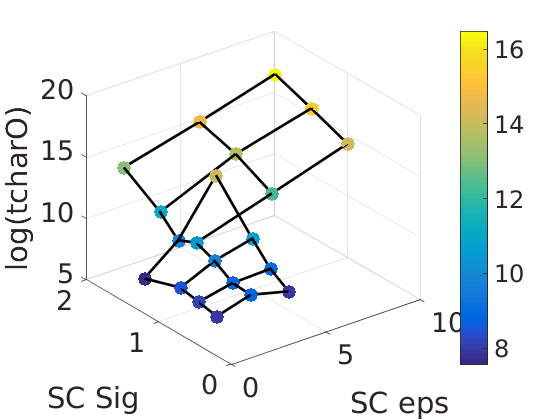

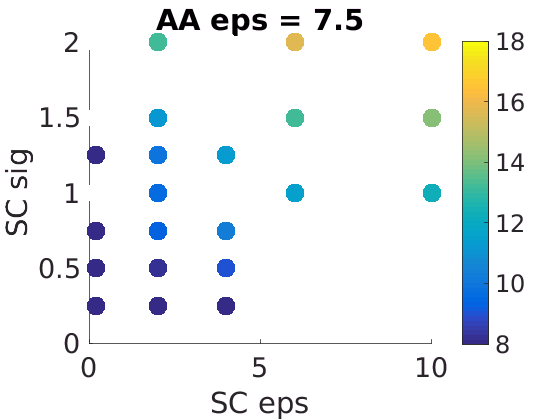

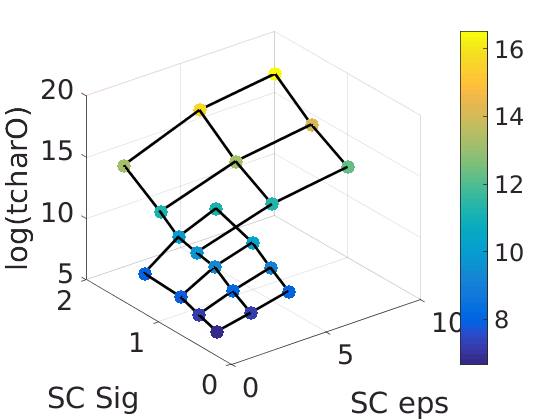

[SCx,Sigx] = meshgrid(SCparams,Sigparams);
SCx = reshape(SCx,length(Sigparams)*length(SCparams),1);
Sigx = reshape(Sigx,length(Sigparams)*length(SCparams),1);

for aa = 1:length(AAnames)
   figure()
   hold on
   %colormap copper
   set(gca,'fontsize',20)
   xlabel('SC eps')
   ylabel('SC sig')
   title(['AA eps = ',num2str(AAparams(aa))])
   sls = tcharOs(aa,:,:)*1825; %1825 ns -> characteristic time in ns
   
   sls = reshape(permute(sls,[3,2,1]),length(SCx),1);
   %sls(sls<0) = 0;
   scatter(SCx,Sigx,200,log(sls),'filled')
   ninds = find(isnan(sls));
   scatter(SCx(ninds),Sigx(ninds),250,[1 1 1],'filled')
   colorbar
   caxis([8 18])
   savefig([savefold AAnames{aa} 'opticTimes'])
   saveas(gcf,[savefold AAnames{aa} 'opticTimes'],'pdf')
   
   f = figure();
hold on
nninds = find(~isnan(sls));
f = errorMesh(SCx(nninds),Sigx(nninds),log(sls(nninds)),0.0*ones(size(sls(nninds))),[0 0 0],f);
figure(f);
colorbar
set(gca,'fontsize',20);
xlabel('SC eps')
ylabel('SC Sig')
zlabel('log(tcharO)')
savefig([savefold AAnames{aa} 'opticTimes3d'])
   saveas(gcf,[savefold AAnames{aa} 'opticTimes3d'],'pdf')
end

## Ratio of optical cluster growth timescale to contact cluster growth timescale

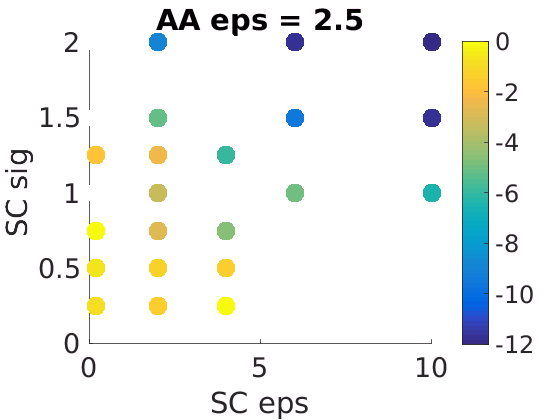

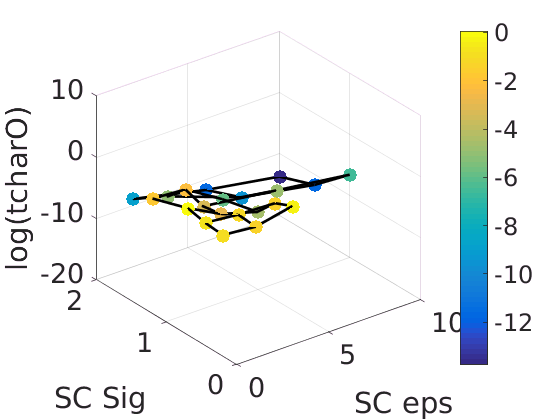

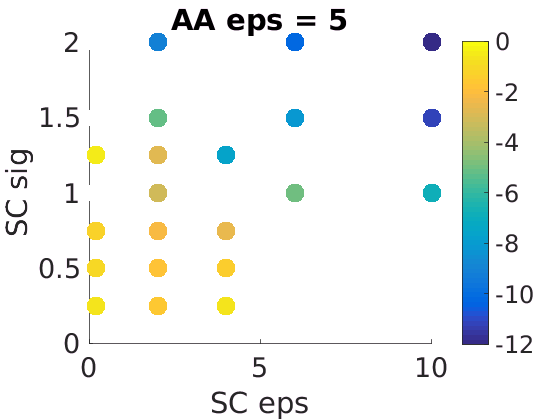

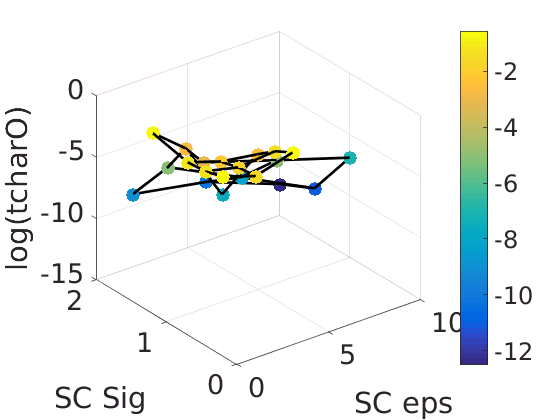

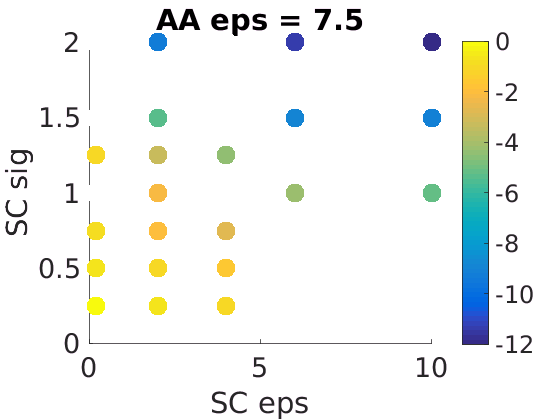

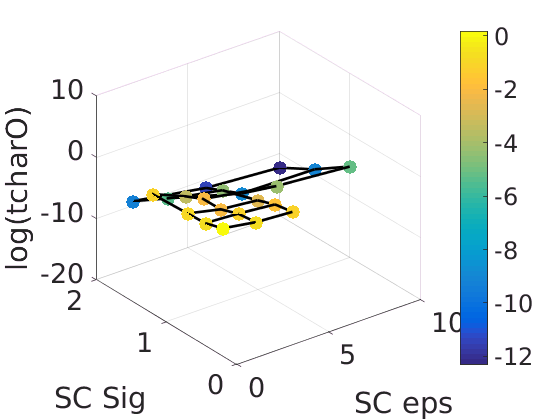

for aa = 1:length(AAnames)
   figure()
   hold on
   %colormap copper
   set(gca,'fontsize',20)
   xlabel('SC eps')
   ylabel('SC sig')
   title(['AA eps = ',num2str(AAparams(aa))])
   tcharOsX = reshape(permute(1./tcharOs(aa,:,:),[3,2,1]),length(SCx),1);
   tcharCsX = reshape(permute(1./tcharCs(aa,:,:),[3,2,1]),length(SCx),1);
   scatter(SCx,Sigx,200,log(tcharOsX./tcharCsX),'filled')
   ninds = find(isnan(sls));
   scatter(SCx(ninds),Sigx(ninds),250,[1 1 1],'filled')
   colorbar
   caxis([-12 0])
    savefig([savefold AAnames{aa} 'OCRatTimes'])
   saveas(gcf,[savefold AAnames{aa} 'OCRatTimes'],'pdf')
   
    f = figure();
hold on
nninds = find(~isnan(sls));
f = errorMesh(SCx(nninds),Sigx(nninds),log(tcharOsX(nninds)./tcharCsX(nninds)),0.0*ones(size(sls(nninds))),[0 0 0],f);
figure(f);
colorbar
set(gca,'fontsize',20);
xlabel('SC eps')
ylabel('SC Sig')
zlabel('log(tcharO)')
end